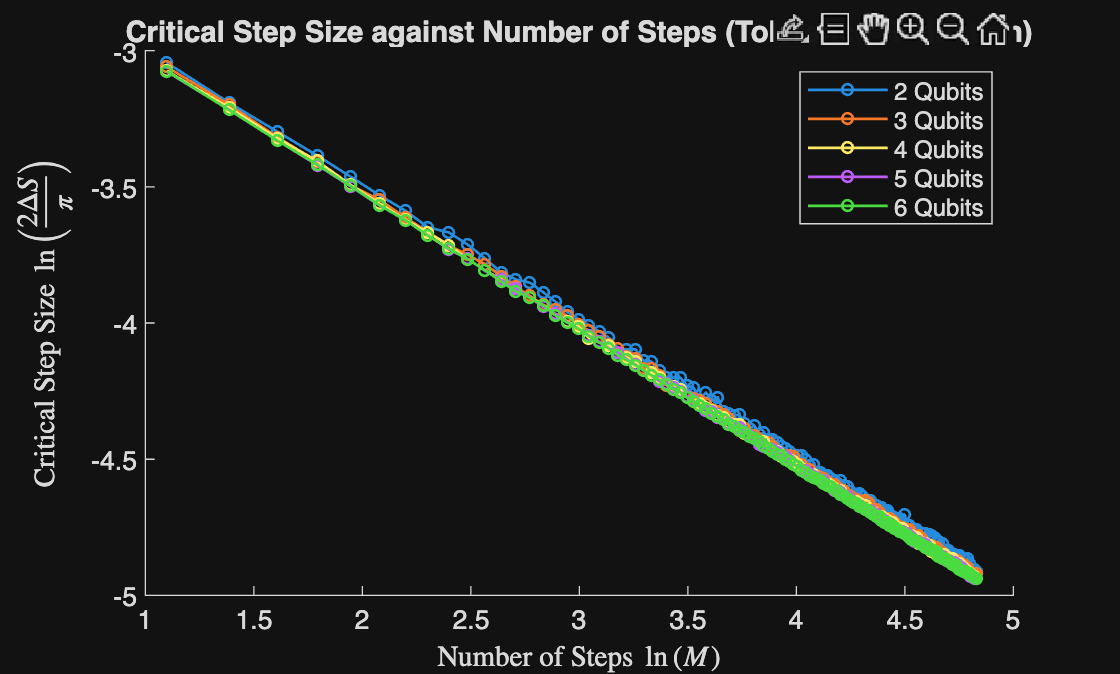

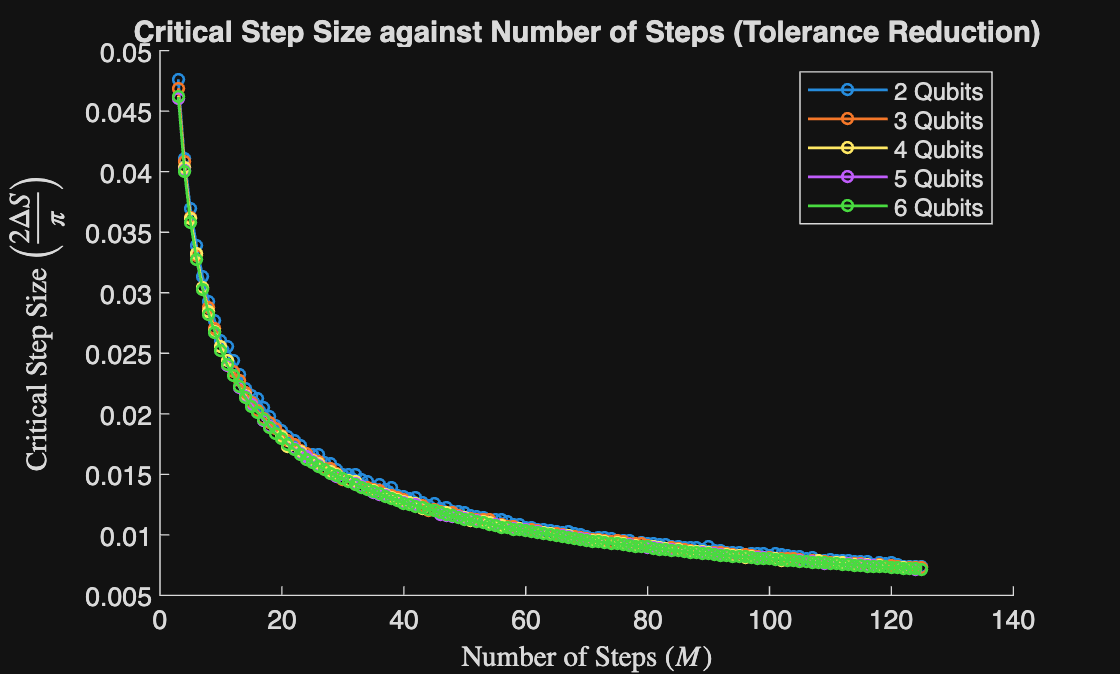

Number_of_Qubits = 6;
Number_of_Walks = 500;

Minimum_Number_of_Steps = 3;
Maximum_Number_of_Steps = 125; 

Decoherence_Exposure = 0.01;
Step_Size_Resolution = 1e-4;

Parameter_Fitting_Algorithm(Number_of_Qubits, Number_of_Walks, Minimum_Number_of_Steps, Maximum_Number_of_Steps, Step_Size_Resolution, Decoherence_Exposure);

function FP = Parameter_Fitting_Algorithm(Number_of_Qubits, Number_of_Walks, Minimum_Number_of_Steps, Maximum_Number_of_Steps, Step_Size_Resolution, Decoherence_Exposure)

FP = zeros(Number_of_Qubits-1, 2);

Critical_Step_Sizes = Critical_Step_Data_Collection_Function(Number_of_Qubits, Number_of_Walks, Minimum_Number_of_Steps, Maximum_Number_of_Steps, Step_Size_Resolution, Decoherence_Exposure);

figure;
hold on;
for j = 1:(Number_of_Qubits-1)

    

    plot(log(Minimum_Number_of_Steps:Maximum_Number_of_Steps), log((2/pi)*Critical_Step_Sizes(j, :)), '-o', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', sprintf('%d Qubits', j+1));
    
    xlabel('Number of Steps $ \ln \left( M \right) $', 'Interpreter', 'latex');
    ylabel('Critical Step Size $ \ln \left( \frac{2 \Delta S}{\pi} \right) $', 'Interpreter', 'latex');
    title(sprintf('Critical Step Size against Number of Steps (Tolerance Reduction)'));
    legend;
end
hold off;

figure;
hold on;

for j = 1:(Number_of_Qubits-1)

    plot(Minimum_Number_of_Steps:Maximum_Number_of_Steps, (2/pi)*Critical_Step_Sizes(j, :), '-o', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', sprintf('%d Qubits', j+1));
    
    xlabel('Number of Steps $ \left( M \right) $', 'Interpreter', 'latex');
    ylabel('Critical Step Size $ \left( \frac{2 \Delta S}{\pi} \right) $', 'Interpreter', 'latex');
    title(sprintf('Critical Step Size against Number of Steps (Tolerance Reduction)'));
    legend;

    

end
hold off;
drawnow;

end


function Data = Critical_Step_Data_Collection_Function(Number_of_Qubits, Number_of_Walks, Minimum_Number_of_Steps, Maximum_Number_of_Steps, Step_Size_Resolution, Decoherence_Exposure)

Data = zeros((Number_of_Qubits-1), (Maximum_Number_of_Steps - Minimum_Number_of_Steps));

    for N = 2:Number_of_Qubits
        for M = Minimum_Number_of_Steps:Maximum_Number_of_Steps

        %------- Bisection Root Finding Algorithm -------%

            Lower_Bound = 0;
            Upper_Bound = pi/2;

            Critical_Step_Size = 0;

            while abs(Lower_Bound - Upper_Bound) > Step_Size_Resolution

               Midpoint = (Lower_Bound + Upper_Bound)/2;
               Midpoint_Value = Random_Walk_Algorithm(N, M, Number_of_Walks, Midpoint) - Precision(Decoherence_Exposure, Midpoint, Number_of_Qubits);
        
                   if abs(Midpoint_Value) <= Step_Size_Resolution
        
                        Critical_Step_Size = Midpoint;
                        break

                   elseif (Midpoint_Value) < 0

                        Upper_Bound = Midpoint;  
                   else

                        Lower_Bound = Midpoint;  
                   end

            end
            
            if Critical_Step_Size == 0
            Critical_Step_Size = (Lower_Bound + Upper_Bound)/2;
            end

            Data(N-1,(M- (Minimum_Number_of_Steps-1))) = Critical_Step_Size;
        end 
    end
end

function RWA = Random_Walk_Algorithm(Number_of_Qubits, Number_of_Steps, Number_of_Walks, Step_Size)

    Final_Distances = zeros(1,Number_of_Walks);

    Dimensions = 2^Number_of_Qubits;
    Component_Volume = Number_of_Walks*Number_of_Steps;
    
    Pole_Vector = zeros(Dimensions, 1);
    Pole_Vector(1) = 1; 
    
    Vector_Database = randn(Dimensions, Component_Volume)+1i*randn(Dimensions, Component_Volume);
    
    for i = 1:Number_of_Walks
     
            Vector = Pole_Vector; 
        
                    for j = 1:Number_of_Steps

                        Selected_Vector = Vector_Database(:,j+(i-1)*Number_of_Steps);

                        Orthogonal_Vector = Selected_Vector - dot(Vector,Selected_Vector)*Vector;

                        Normalized_Vector = Orthogonal_Vector / norm(Orthogonal_Vector);

                        Vector = (cos(Step_Size) * Vector) + (sin(Step_Size) * Normalized_Vector);

                    end 

              Final_Distances(:,i) = Fubini_Study_Distance(Pole_Vector, Vector);
    end 

    RWA = pi*0.5 - mean(Final_Distances);
end 

function FBS = Fubini_Study_Distance(Vector_1, Vector_2)

    FBS = acos(abs(dot(Vector_1,Vector_2)));
end

function Precision = Precision(Decoherence_Exposure, Step_Size, Number_of_Qubits)
    
    Dimensionality = 2 ^ Number_of_Qubits;
    Coherence_Retention_Factor = exp(-Decoherence_Exposure*Step_Size);

    Precision = acos(sqrt(1/(Dimensionality*Coherence_Retention_Factor)));
end